# RATE CONTROLLER EXTENDED DESIGN APPROACH

clc
clearvars
set(0, 'DefaultFigureWindowStyle', 'normal');
addpath(genpath('.'))
[opt_time, opt_bode, opt_nichols] = setPlots;

FS = 1800;
TS = 1/FS;

## System Properties

### Gimbals

J = 40*1e-6;
n = 1.0; % Gear Ratio
Jn = J/n^2;
Plant = tf(1, [Jn 0]);
Plant.Name = '1/Js';
Kt = 9.55e-3;

### Gyro

sensorBW = 130; %[Hz]
Sensor = tf((2*pi*sensorBW)^2, [1 2*0.5326*(2*pi*sensorBW) (2*pi*sensorBW)^2]);
Sensor.Name = 'Sensor no Delay';

Sensor_d = Sensor;
Sensor_d.IODelay = TS*1.0;
Sensor_d.Name = sprintf('Sensor with %.2f [cycles] Delay', Sensor_d.IODelay/TS);

### Sensor View

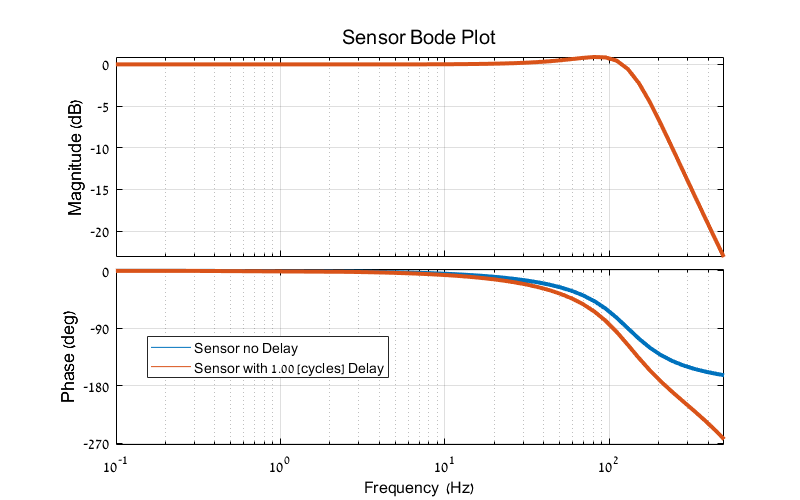

figure('Position',[0 0 800 500])
bodeplot(Sensor, Sensor_d,opt_bode);
xlim([0.1 500])
title('Sensor Bode Plot');

set(findall(gcf, 'type', 'line'), 'LineWidth', 3);
legend('show', 'Location','best', 'ItemHitFcn', @clickLegendToHide);

## Controller Design

### Initial View

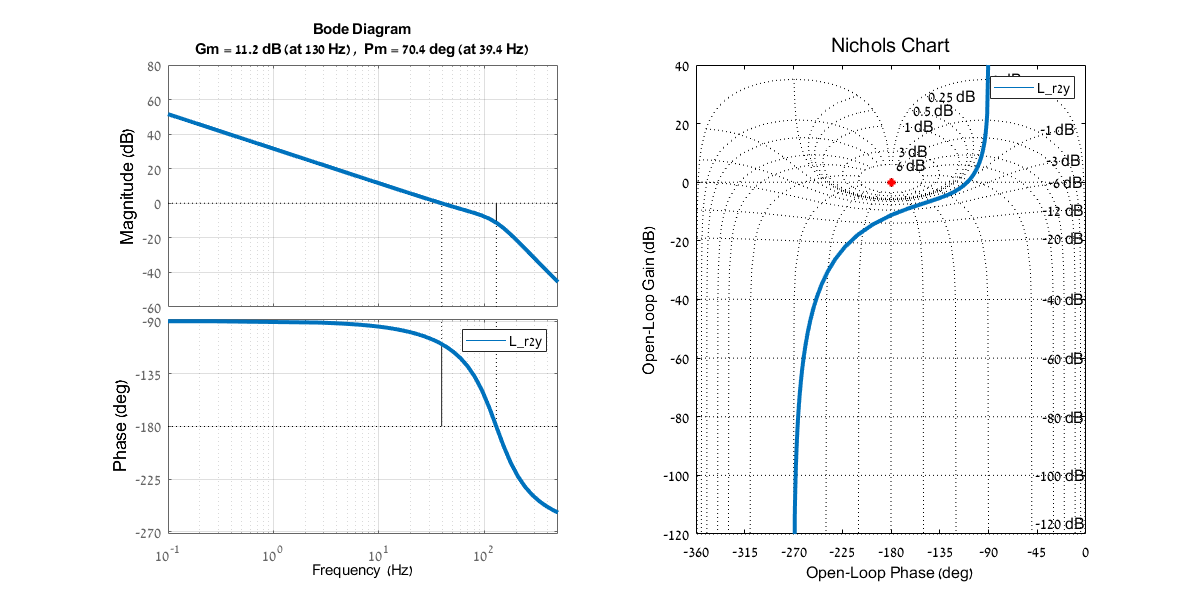

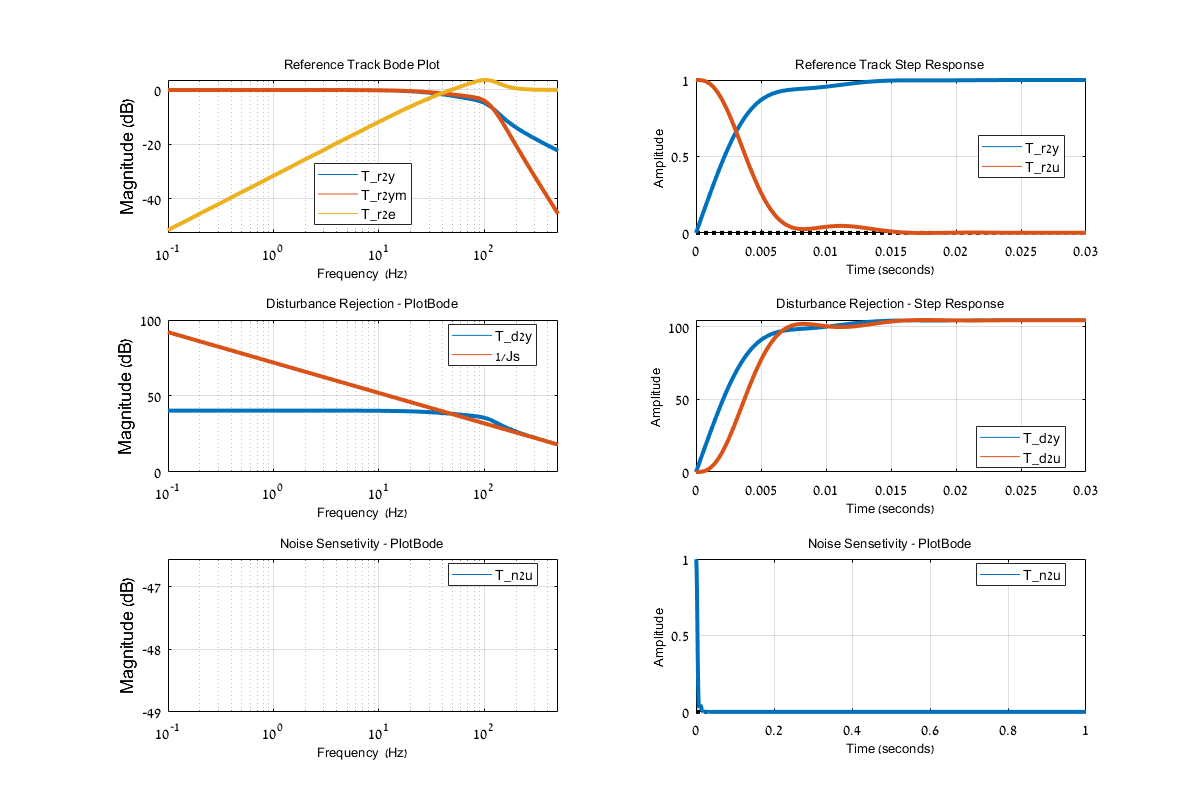

initial_design = get_design_functions(1, Kt, Plant, Sensor, 1);
plot_control_design(initial_design, 1, 1, 0)

### Step1 - Lag Controller

f_LAG = 5;
% Kp = 0.05;
Kp = 0.0002;

C_LAG = Kp*tf([1 (2*pi*f_LAG)], [1 0]);
C_LAG.Name = 'Lag Controller';
design_Step1 = get_design_functions(C_LAG, Kt, Plant, Sensor_d, 1);

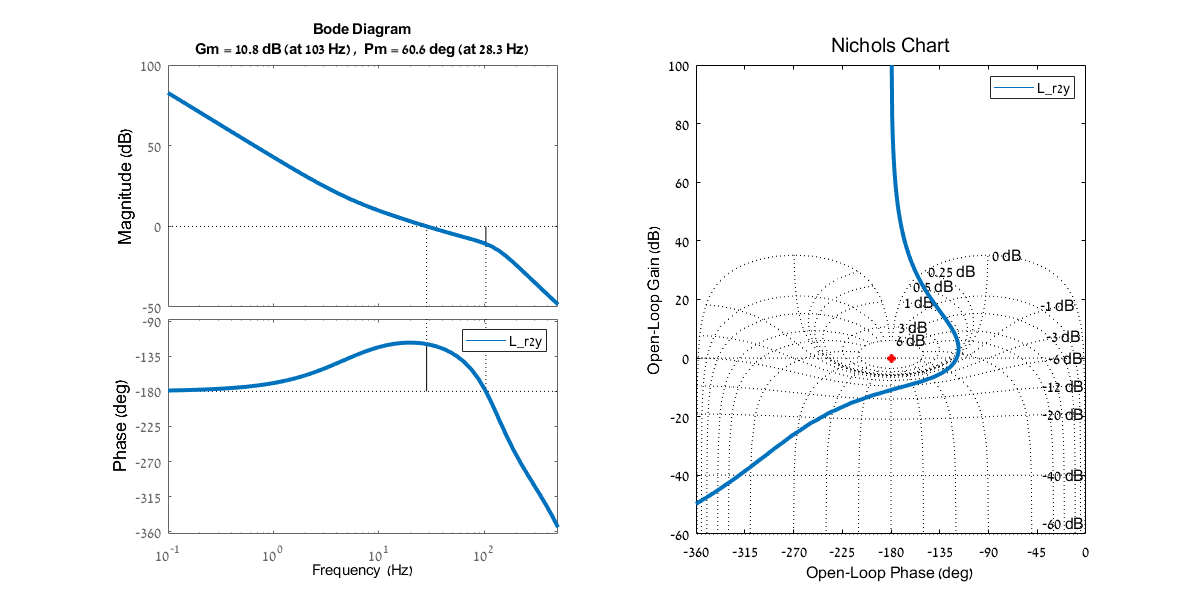

plot_control_design(design_Step1, 1, 0, 0)

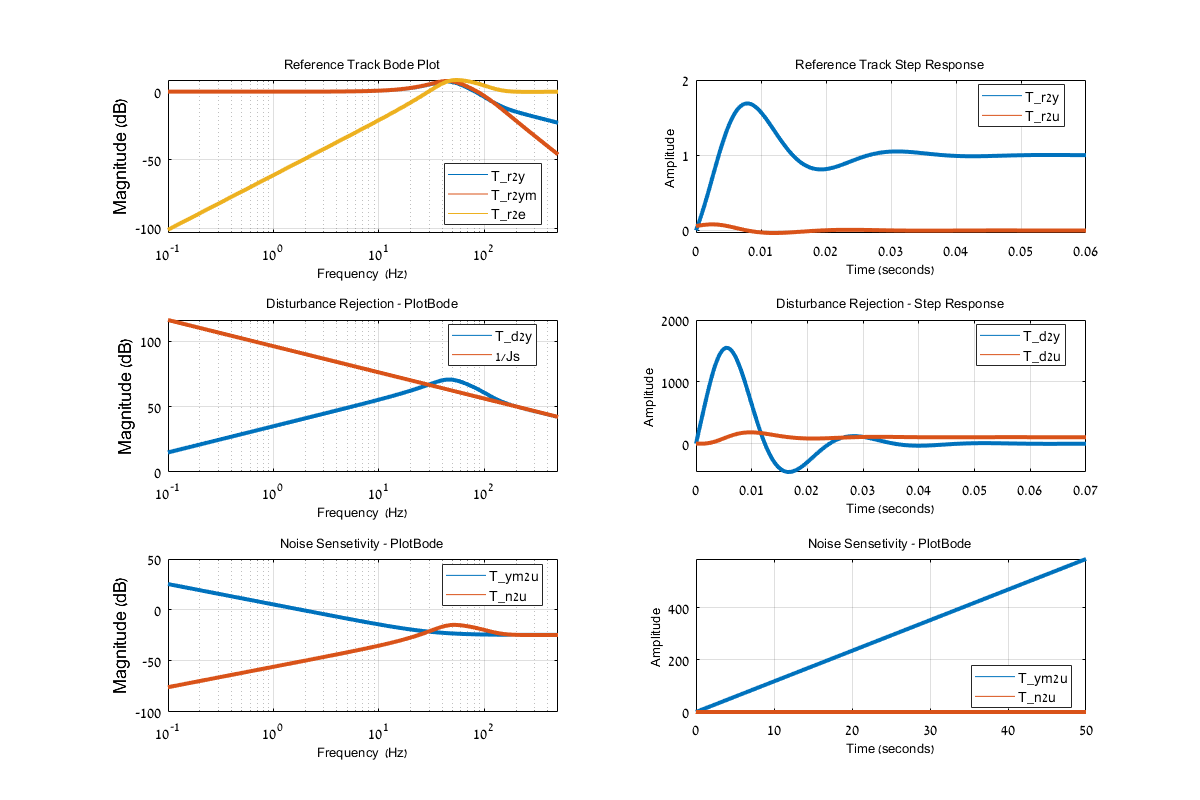

plot_control_design(design_Step1, 0, 1, 0)

### Step2 - Lead Filter

f_LEAD = 30;
phiM_Deg = 40;

a = (1 + sind(phiM_Deg))/(1 - sind(phiM_Deg));
sqa = sqrt(a);

C_LEAD = tf([a sqa*(2*pi*f_LEAD)], [1 sqa*(2*pi*f_LEAD)]);
% C_LEAD = tf(1, [1]);
C_LEAD.Name = 'Lead Compensator';
design_Step2 = get_design_functions(C_LAG, Kt, Plant, Sensor_d, C_LEAD);

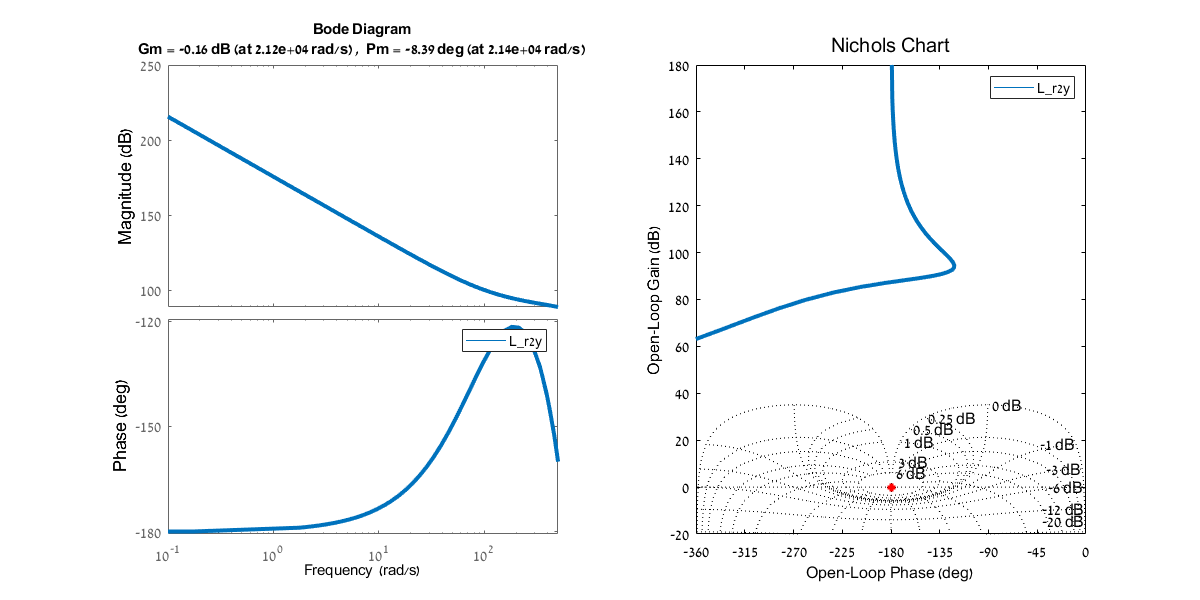

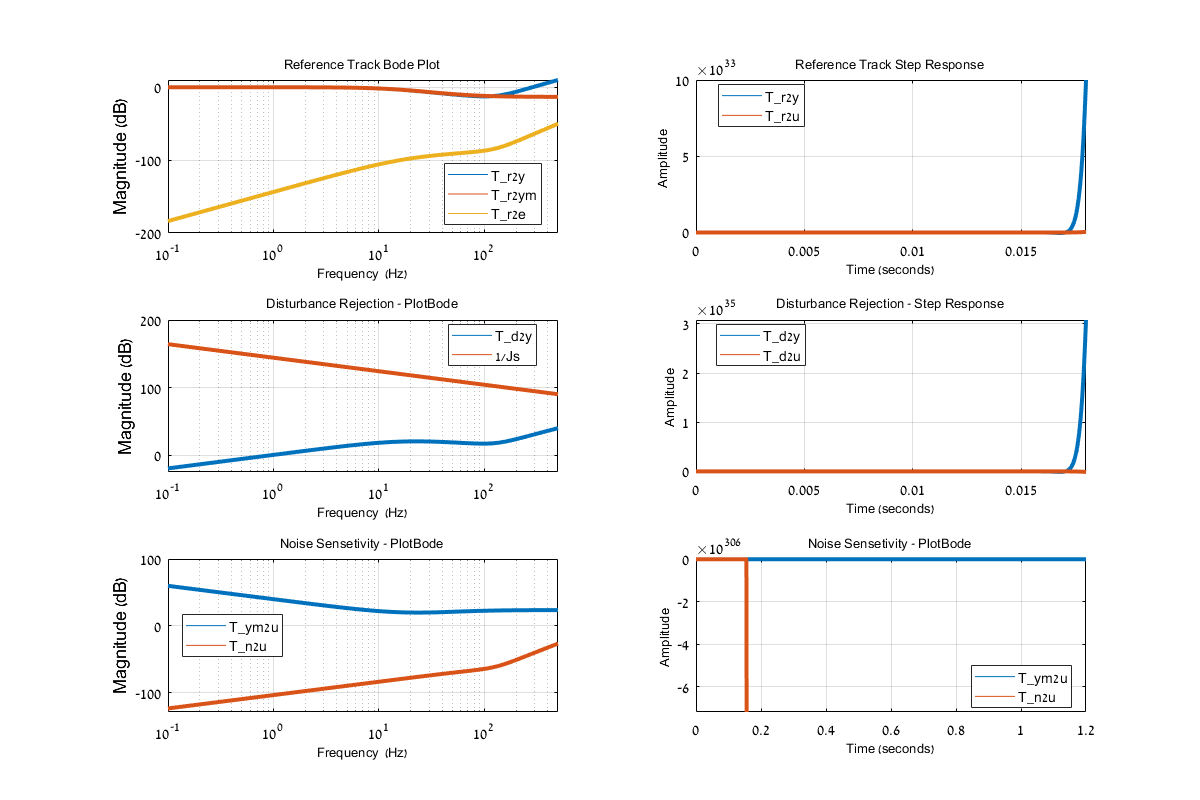

plot_control_design(design_Step2, 1, 1, 0)

## Adding Filters

### Filter Design - Option 5

Notch_Struct = RFSNotchDesign(TS);

Undefined function or variable 'RFSNotchDesign'.


BSFc =  Notch_Struct.Notch_c;
BSFc.Name = 'Band Stop Filter';

C_LAG_Notch = series(C_LAG,BSFc);
C_LAG_Notch.Name = 'C_LAG_Notch';

figure('Position',[0 0 1200 500])
set(opt_bode, 'PhaseWrapping', 'on')
bodeplot(BSFc, opt_bode)
set_linewidth_ctrl
legend('show', 'Location', 'best', 'ItemHitFcn', @clickLegendToHide)
xlim([10 500])

### Filtered Design

design_Step2_filt = get_design_functions(C_LAG_Notch, Kt, Plant, Sensor_d, C_LEAD);
plot_control_design(design_Step2_filt, 1, 1, 0)

## Accounting for uncertain parameters 

Kt_unc = ureal('kt_unc', 0.05, 'percent', 10);
J_unc = ureal('J_unc', J, 'percent', 5);

Plant_unc = tf(1, [J_unc 0]);
Plant_unc.Name = '1/J_{unc}';

design_Step2_unc = get_design_functions(C_LAG_Notch, Kt_unc, Plant_unc, Sensor_d, C_LEAD);
plot_control_design(design_Step2_unc, 1, 1, 0)

### Going Parameters

[z,p,k] = zpkdata(C_LAG);
zpk(z,p,k, 'DisplayFormat', 'roots')
[z,p,k] = zpkdata(C_LEAD);
zpk(z,p,k, 'DisplayFormat', 'timeconstant')

plot_control_design(design_Step2, 0, 0, 1)

## Compare Designs

C_LAG_prev = 4.45*tf([1 314.1],[1 0]);
C_LAG_prev.Name = 'Lag Controller Prev.';
C_LEAD_prev = tf([0.01093 1],[0.001448 1]);
C_LEAD_prev.Name = 'Lead Controller Prev.';

design_prev = get_design_functions(C_LAG_prev, Kt, Plant, Sensor_d, C_LEAD_prev);
plot_control_design(design_prev, 1, 0, 0)

figure('Position',[0 0 1200 500])

subplot(1,3,1:2)
bodeplot(design_Step2.L,design_prev.L, opt_bode)
set(findobj(gcf, 'Type', 'Line'), 'LineWidth', 2)
set(findobj(gcf, 'Type', 'Axes'), 'Fontsize', 12)
xlim([1e-3 1e3])
legend('show', 'Location', 'best', 'ItemHitFcn', @clickLegendToHide)

subplot(1,3,3)
nicholsplot(design_Step2.L, design_prev.L, opt_nichols)
set(findobj(gcf, 'Type', 'Line'), 'LineWidth', 2)
set(findobj(gcf, 'Type', 'Axes'), 'Fontsize', 14)
legend('show', 'Location', 'best', 'ItemHitFcn', @clickLegendToHide)
xlim([-360 0])

figure('Position',[0 0 1200 500])

subplot(1,2,1)
b1 = bodeplot(design_Step2.T_r2y,design_prev.T_r2y, opt_bode);
b1.PhaseVisible = 'off';
set(findobj(gcf, 'Type', 'Line'), 'LineWidth', 2)
set(findobj(gcf, 'Type', 'Axes'), 'Fontsize', 14)
legend('show', 'Location','best', 'ItemHitFcn', @clickLegendToHide)

subplot(1,2,2)
stepplot(design_Step2.T_d2y,design_prev.T_d2y, opt_nichols);
set(findobj(gcf, 'Type', 'Line'), 'LineWidth', 2)
set(findobj(gcf, 'Type', 'Axes'), 'Fontsize', 14)
legend('show', 'Location','best', 'ItemHitFcn', @clickLegendToHide)

figure('Position',[0 0 800 500])

b1 = bodeplot(design_Step2.T_d2y,design_prev.T_d2y, opt_bode);
b1.PhaseVisible = 'off';
set(findobj(gcf, 'Type', 'Line'), 'LineWidth', 2)
set(findobj(gcf, 'Type', 'Axes'), 'Fontsize', 14)
legend('show', 'Location','best', 'ItemHitFcn', @clickLegendToHide)